% Load Data
load('MBD.mat')

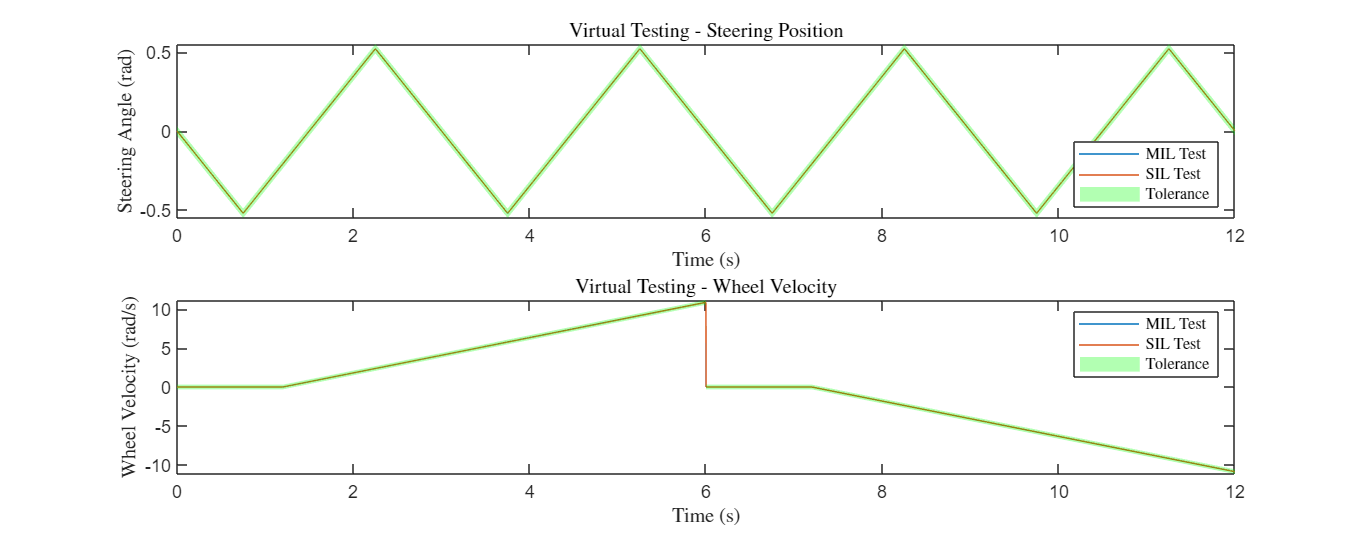

% MIL & SIL

figure('Renderer', 'painters', 'Position', [10 10 910 360])

subplot(2,1,1)
plot(data{1}{1}{1}.Values)
hold on
plot(data{2}{1}{1}.Values)
x = linspace(0,12,length(data{1}{1}{1}.Values.Data)); % Using MIL as comparison basis
y = data{1}{1}{1}.Values.Data';
x_tol = [x x(end:-1:1)];
y_tol = [y+0.03 y(end:-1:1)-0.03];
tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
title("Virtual Testing - Steering Position","Interpreter","latex")
xlabel("Time (s)","Interpreter","latex")
ylabel("Steering Angle (rad)","Interpreter","latex")
legend("MIL Test","SIL Test","Tolerance","Location","SE","Interpreter","latex")

subplot(2,1,2);
plot(data{1}{1}{2}.Values)
hold on
plot(data{2}{1}{2}.Values)
x = linspace(0,12,length(data{1}{1}{2}.Values.Data)); % Using MIL as comparison basis
y = data{1}{1}{2}.Values.Data';
x_tol = [x x(end:-1:1)];
y_tol = [y+0.3 y(end:-1:1)-0.3];
tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
title("Virtual Testing - Wheel Velocity","Interpreter","latex")
xlabel("Time (s)","Interpreter","latex")
ylabel("Wheel Velocity (rad/s)","Interpreter","latex")
legend("MIL Test","SIL Test","Tolerance","Location","NE","Interpreter","latex")

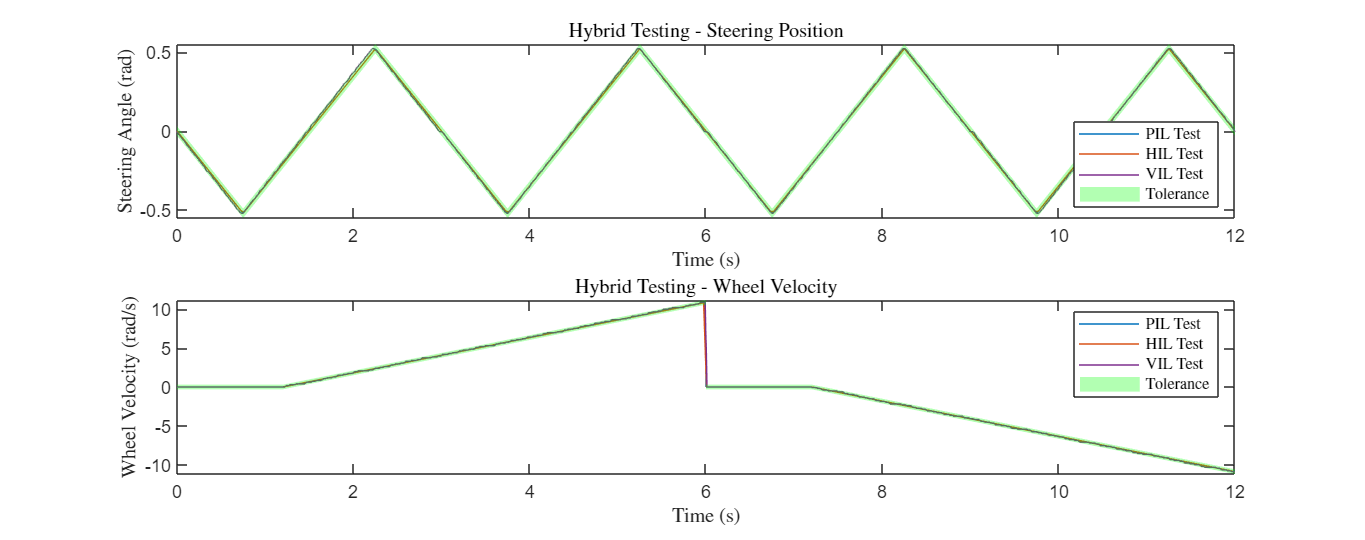

% PIL, HIL & VIL

figure('Renderer', 'painters', 'Position', [10 10 910 360])

subplot(2,1,1)
plot(data{3}{1}{1}.Values)
hold on
plot(data{4}{1}{1}.Values)
plot(data{5}{1}{1}.Values,'Color','#7E2F8E')
x = linspace(0,12,length(data{1}{1}{1}.Values.Data)); % Using MIL as comparison basis
y = data{1}{1}{1}.Values.Data';
x_tol = [x x(end:-1:1)];
y_tol = [y+0.03 y(end:-1:1)-0.03];
tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
title("Hybrid Testing - Steering Position","Interpreter","latex")
xlabel("Time (s)","Interpreter","latex")
ylabel("Steering Angle (rad)","Interpreter","latex")
legend("PIL Test","HIL Test","VIL Test","Tolerance","Location","SE","Interpreter","latex")

subplot(2,1,2);
plot(data{3}{1}{2}.Values)
hold on
plot(data{4}{1}{2}.Values)
plot(data{5}{1}{2}.Values,'Color','#7E2F8E')
x = linspace(0,12,length(data{1}{1}{2}.Values.Data)); % Using MIL as comparison basis
y = data{1}{1}{2}.Values.Data';
x_tol = [x x(end:-1:1)];
y_tol = [y+0.3 y(end:-1:1)-0.3];
tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
title("Hybrid Testing - Wheel Velocity","Interpreter","latex")
xlabel("Time (s)","Interpreter","latex")
ylabel("Wheel Velocity (rad/s)","Interpreter","latex")
legend("PIL Test","HIL Test","VIL Test","Tolerance","Location","NE","Interpreter","latex")

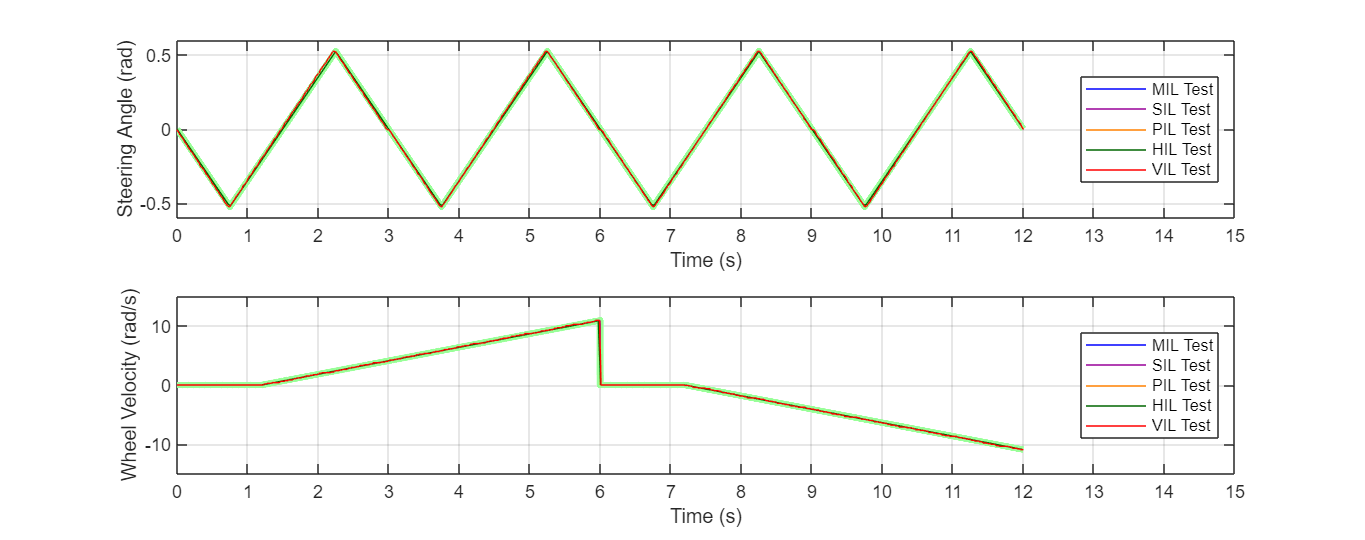

% MIL, SIL, PIL, HIL & VIL

figure('Renderer', 'painters', 'Position', [10 10 910 360])

subplot(2,1,1)
plot(data{1}{1}{1}.Values,'LineWidth',3.5,'Color','#99FF99') % Tolerance band using MIL as comparison basis
hold on
plot(data{1}{1}{1}.Values,'Color','#0000FF')
plot(data{2}{1}{1}.Values,'Color','#990099')
plot(data{3}{1}{1}.Values,'Color','#FF8000')
plot(data{4}{1}{1}.Values,'Color','#006600')
plot(data{5}{1}{1}.Values,'Color','#FF0000')
% x = linspace(0,12,length(data{1}{1}{1}.Values.Data)); % Using MIL as comparison basis
% y = data{1}{1}{1}.Values.Data';
% x_tol = [x x(end:-1:1)];
% y_tol = [y+0.03 y(end:-1:1)-0.03];
% tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
xlim([0,15])
xticks(0:1:15)
ylim([-0.6,0.6])
grid on
title("")
xlabel("Time (s)")
ylabel("Steering Angle (rad)")
legend("","MIL Test","SIL Test","PIL Test","HIL Test","VIL Test","Location","E","Color",[1, 1, 1, 0.8])

subplot(2,1,2);
plot(data{1}{1}{2}.Values,'LineWidth',3.5,'Color','#99FF99')  % Tolerance band using MIL as comparison basis
hold on
plot(data{1}{1}{2}.Values,'Color','#0000FF')
plot(data{2}{1}{2}.Values,'Color','#990099')
plot(data{3}{1}{2}.Values,'Color','#FF8000')
plot(data{4}{1}{2}.Values,'Color','#006600')
plot(data{5}{1}{2}.Values,'Color','#FF0000')
% x = linspace(0,12,length(data{1}{1}{2}.Values.Data)); % Using MIL as comparison basis
% y = data{1}{1}{2}.Values.Data';
% x_tol = [x x(end:-1:1)];
% y_tol = [y+0.3 y(end:-1:1)-0.3];
% tol_band = fill(x_tol,y_tol,'green','FaceAlpha',0.3,'EdgeColor','none');
hold off
xlim([0,15])
xticks(0:1:15)
ylim([-15,15])
grid on
title("")
xlabel("Time (s)")
ylabel("Wheel Velocity (rad/s)")
legend("","MIL Test","SIL Test","PIL Test","HIL Test","VIL Test","Location","E","Color",[1, 1, 1, 0.8])